clear all
close all
clc
fun = inline('exp(x)+exp(-x)+exp(y)+exp(-y)','x','y');
dfunx = inline('exp(x)-exp(-x)','x','y');
dfuny = inline('exp(y)-exp(-y)','x','y'); 
x0 = -4;
y0 = 4;
EPS = 0.001; %error limit
px = 0.01; %x step size
py = 0.02; %y step size
[x,y,n,point] = Tidu(fun,dfunx,dfuny,x0,y0,EPS,px,py)

x = -0.1532

y = 0.0114

n = 125

point =    -4.0000    4.0000  109.2329
   -3.4542    2.9084   50.0467
   -3.1382    2.5429   35.9011
   -2.9080    2.2902   28.3526
   -2.7253    2.0947   23.5731
   -2.5734    1.9347   20.2527
   -2.4430    1.7991   17.8047
   -2.3288    1.6815   15.9233
   -2.2271    1.5778   14.4319
   -2.1355    1.4850   13.2210


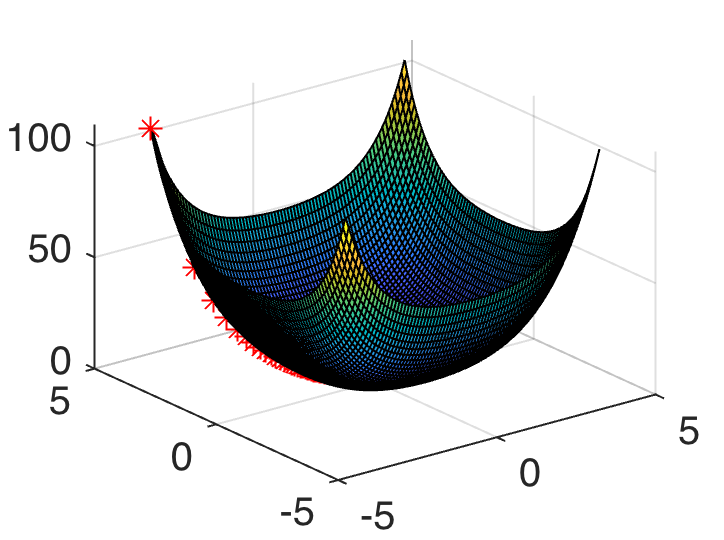

figure
x = -4:0.1:4;
y = -4:0.1:4;
[x,y] = meshgrid(x,y);
z = exp(x)+exp(-x)+exp(y)+exp(-y);
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');

function [x,y,n,point] = Tidu(fun,dfunx,dfuny,x,y,EPS,px,py)
    a = feval(fun,x,y);
    b = a+1;
    n=1;
    point(n,:) = [x y a];
    while (abs(a-b) >= EPS)  
      a = feval(fun,x,y);
      x = x - px*(feval(dfunx,x,y));
      y = y - py*(feval(dfuny,x,y));
      b = feval(fun,x,y); 
      n = n+1;
      point(n,:) = [x y b]; 
    end
end